format long;
syms t;
f(-pi/4)

ans =     -4.547473508864641e-13


f(pi/4)

ans =     -4.547473508864641e-13


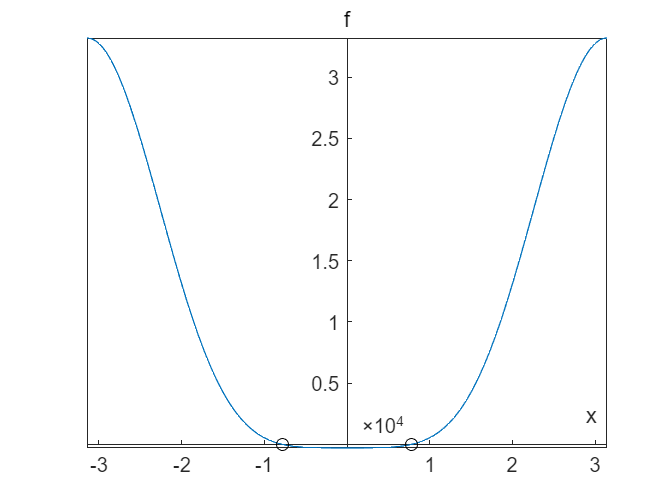

ezplot(@f,[-pi,pi]);hold on%画出[-pi,pi]区间内的f图像
plot([pi/4 -pi/4],[0 0],'ko');%描出点(-pi/4,0),(pi/4,0)
ax=gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';%设置过原点的坐标轴
axis([-inf inf -inf inf]);%坐标轴范围随函数值域而调整

x01=fzero(@f,pi/4)

x01 =    0.785398163397449


x02=fzero(@f,-pi/4)

x02 =   -0.785398163397449


Ef1=abs(x01-pi/4)%前向误差

Ef1 =      3.330669073875470e-16


Ef2=abs(x02+pi/4)

Ef2 =      3.330669073875470e-16


Eb1=abs(f(x01))%后向误差

Eb1 =      2.273736754432321e-13


Eb2=abs(f(x02))

Eb2 =      2.273736754432321e-13


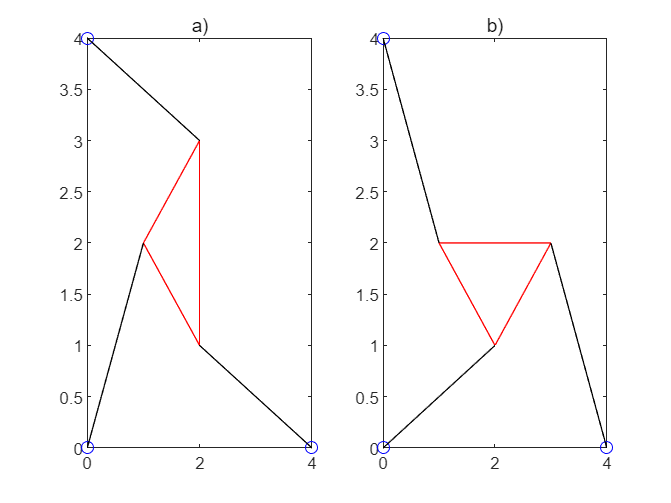

figure;%创建图窗窗口
subplot(1,2,1);%在第一个分块创建坐标区
plot([1 2 2 1],[2 3 1 2],'r');hold on%画三角形
plot([0 4 0],[0 0 4],'bo');hold on%描出锚点
plot([0 1 0],[0 2 0],'k');hold on
plot([4 2 4],[0 1 0],'k');hold on
plot([0 2 0],[4 3 4],'k')%画出支杆
title('a)');%给图像标号
subplot(1,2,2);%在第二个分块创建坐标区
plot([2 1 3 2],[1 2 2 1],'r');hold on%画三角形
plot([0 4 0],[0 0 4],'bo');hold on%描出锚点
plot([0 2 0],[0 1 0],'k');hold on
plot([4 3 4],[0 2 0],'k');hold on
plot([0 1 0],[4 2 4],'k')%画出支杆
title('b)');%给图像标号

function out=f(theta)%为了求得theta,构造f(theta)=0所需f
format long;
L1=2;
L2=sqrt(2);
L3=sqrt(2);
gamma=pi/2;
p1=sqrt(5);
p2=sqrt(5);
p3=sqrt(5);
x1=4;
x2=0;
y2=4;%直接给参数赋值参数
A2=L3.*cos(theta)-x1;
B2=L3.*sin(theta);
A3=L2.*(cos(theta).*cos(gamma)-sin(theta).*sin(gamma))-x2;
B3=L2.*(cos(theta).*sin(gamma)+sin(theta).*cos(gamma))-y2;
D=2.*(A2.*B3-B2.*A3);
M1=p2.^2-p1.^2-A2.^2-B2.^2;
M2=p3.^2-p1.^2-A3.^2-B3.^2;
N1=B3.*M1-B2.*M2;
N2=-A3.*M1+A2.*M2;%按照上述数学公式推导，计算所需关系式
out=N1.^2+N2.^2-p1.^2*D.^2;%输出函数
end